clc, clear, close all
load("data.mat")
num_points = 1000;
Data_r = [Data(:,1:2) randi(2,2*num_points,1)];
Param = make_initial_guess();
[Data_f, Param_f] = EM(Data_r, Param);

iteration: 1, error: 15.7818, mu1: [69.5279 190.8296], mu2: [61.1260 124.2653] 
iteration: 2, error: 2.1347, mu1: [69.3959 189.8509], mu2: [60.9896 123.1262] 
iteration: 3, error: 1.8183, mu1: [69.2984 188.9254], mu2: [60.8616 122.2478] 
iteration: 4, error: 1.6111, mu1: [69.2006 188.1631], mu2: [60.7570 121.4117] 
iteration: 5, error: 1.3452, mu1: [69.1172 187.5342], mu2: [60.6717 120.7061] 
iteration: 6, error: 0.6737, mu1: [69.0743 187.2153], mu2: [60.6301 120.3566] 
iteration: 7, error: 0.3370, mu1: [69.0531 187.0513], mu2: [60.6090 120.1862] 
iteration: 8, error: 0.6064, mu1: [69.0162 186.7462], mu2: [60.5700 119.8897] 
iteration: 9, error: 0.2021, mu1: [69.0038 186.6447], mu2: [60.5570 119.7907] 
iteration: 10, error: 0.2032, mu1: [68.9886 186.5614], mu2: [60.5469 119.6726] 
iteration: 11, error: 0.0673, mu1: [68.9849 186.5243], mu2: [60.5421 119.6431] 
iteration: 12, error: 0.0000, mu1: [68.9849 186.5243], mu2: [60.5421 119.6431] 


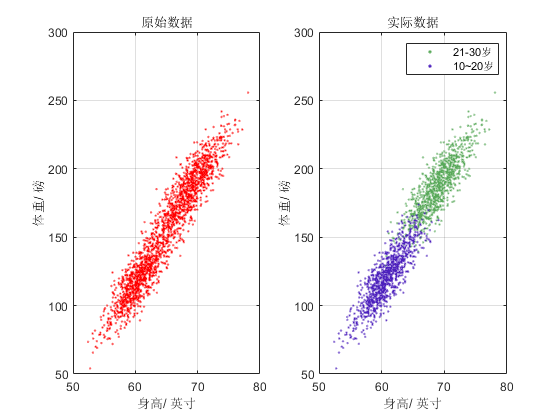

figure; subplot(1,2,1);
scatter(Data(:,1), Data(:,2), 10, '.','r');
grid on; box on;
title('原始数据')
xlabel('身高/ 英寸')
ylabel('体重/ 磅')
Data1 = Data(Data(:,3)==1, :);
Data2 = Data(Data(:,3)==2, :);
subplot(1,2,2);hold on
scatter(Data1(:,1), Data1(:,2), 10, '.','CData',[89 169 90]/255);
scatter(Data2(:,1), Data2(:,2), 10, '.','CData',[77 33 189]/255);
grid on; box on;
title('实际数据')
xlabel('身高/ 英寸')
ylabel('体重/ 磅')
legend('21-30岁','10~20岁')

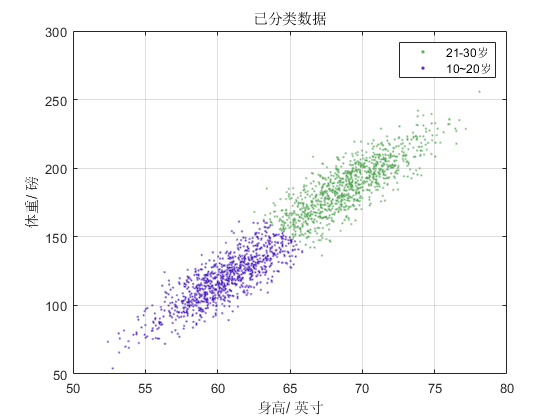

figure;
Data_f1 = Data_f(Data_f(:,3)==1, :);
Data_f2 = Data_f(Data_f(:,3)==2, :);
hold on
scatter(Data_f1(:,1), Data_f1(:,2), 10,'.', 'CData',[89 169 90]/255);
scatter(Data_f2(:,1), Data_f2(:,2), 10, '.','CData',[77 33 189]/255);
grid on; box on;
xlabel('身高/ 英寸')
ylabel('体重/ 磅')
title('已分类数据');
legend('21-30岁','10~20岁')

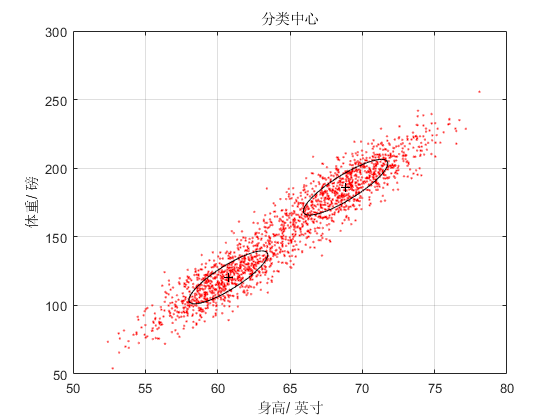

CPU time used for EM_GM:  1.89s
Number of iterations: 4


W =           0.49017126091228          0.50982873908772


M =           60.7370394060125          68.8417988296908
          120.437821455594          186.110558258876


V = V(:,:,1) =

          7.41610837939065           44.813816711462
           44.813816711462          371.054986662379


V(:,:,2) =

          8.49401291076708          50.5398525972711
          50.5398525972711           412.38502202243


L =            -17940.15749331


center = [63.73 135.6];
male_center = [69.02 186.3];
delta = center - [60.81 120.7];
X = zeros(2000,2);
X(1:1000,:) = Data(1:1000,1:2);
X(1001:2000,:) = Data(1001:2000,1:2);
[W,M,V,L] = EM_GM(X,2,[],[],1,[])

function d = calc_distance(Param, Param_)
d = norm(Param.mu1 - Param_.mu1) + norm(Param.mu2 - Param_.mu2);
end

function p = prob(point, mu, sigma, lambda)
p = lambda;
for ii = 1:length(point)
    x=normpdf(point(1,ii), mu(1,ii), sigma(ii,ii));
    p = p * normpdf(point(1,ii), mu(1,ii), sigma(ii,ii));
end
end

function Param = maximization(Data, Param)

points_in_cluster1 = Data(Data(:,3) == 1,:);
points_in_cluster2 = Data(Data(:,3) == 2,:);

percent_cluster1 = size(points_in_cluster1,1) / size(Data,1);
percent_cluster2 = 1 - percent_cluster1;

% calculate the weights
Param.lambda = [percent_cluster1, percent_cluster2];

% calculate the means
Param.mu1 = [mean(points_in_cluster1(:,1)), mean(points_in_cluster1(:,2))];
Param.mu2 = [mean(points_in_cluster2(:,1)), mean(points_in_cluster2(:,2))];

% calculate the variances
Param.sigma1 = [std(points_in_cluster1(:,1)) 0; 0 std(points_in_cluster1(:,2))];
Param.sigma2 = [std(points_in_cluster2(:,1)) 0; 0 std(points_in_cluster2(:,2))];

end

function Param = make_initial_guess()

Param = struct();
Param.mu1 = [69, 187];
Param.mu2 = [63.7, 135.9];
Param.sigma1 = [2.86 0; 0 19.8];
Param.sigma2 = [2.69 0; 0 19.02];
Param.lambda = [0.5, 0.5];
end

function Data = expectation(Data, Param)


for ii = 1: size(Data,1)
    x = Data(ii, 1:2);
    p_cluster1 = prob(x, Param.mu1, Param.sigma1, Param.lambda(1,1));
    p_cluster2 = prob(x, Param.mu2, Param.sigma2, Param.lambda(1,2));
    
    if p_cluster1 > p_cluster2
        Data(ii, 3) = 1;
    else
        Data(ii, 3) = 2;
    end
end
end

function [Data_f, Param_f] = EM(Data, Param)
shift = 10000;
iter = 0;
epsilon = 0.001;
formatSpec = 'iteration: %d, error: %2.4f, mu1: [%2.4f %2.4f], mu2: [%2.4f %2.4f] \n';

while shift > epsilon
    iter = iter + 1;
    % E-step
    Data_ = expectation(Data, Param);
    % M-step
    Param_ = maximization(Data_, Param);
    shift = calc_distance(Param, Param_);
    fprintf(formatSpec, iter, shift, Param_.mu1, Param_.mu2);
    Data = Data_;
    Param = Param_;
    clear Data_ Param_
end
Data_f = Data;
Param_f = Param;
end

function [W,M,V,L] = EM_GM(X,k,ltol,maxiter,pflag,Init)

%%%% Validate inputs %%%%
if nargin <= 1
    disp('EM_GM must have at least 2 inputs: X,k!/n')
    return
elseif nargin == 2
    ltol = 0.1; maxiter = 1000; pflag = 0; Init = [];
    err_X = Verify_X(X);
    err_k = Verify_k(k);
    if err_X || err_k, return; end
elseif nargin == 3
    maxiter = 1000; pflag = 0; Init = [];
    err_X = Verify_X(X);
    err_k = Verify_k(k);
    [ltol,err_ltol] = Verify_ltol(ltol);
    if err_X || err_k || err_ltol, return; end
elseif nargin == 4
    pflag = 0;  Init = [];
    err_X = Verify_X(X);
    err_k = Verify_k(k);
    [ltol,err_ltol] = Verify_ltol(ltol);
    [maxiter,err_maxiter] = Verify_maxiter(maxiter);
    if err_X || err_k || err_ltol || err_maxiter, return; end
elseif nargin == 5
    Init = [];
    err_X = Verify_X(X);
    err_k = Verify_k(k);
    [ltol,err_ltol] = Verify_ltol(ltol);
    [maxiter,err_maxiter] = Verify_maxiter(maxiter);
    [pflag,err_pflag] = Verify_pflag(pflag);
    if err_X || err_k || err_ltol || err_maxiter || err_pflag, return; end
elseif nargin == 6
    err_X = Verify_X(X);
    err_k = Verify_k(k);
    [ltol,err_ltol] = Verify_ltol(ltol);
    [maxiter,err_maxiter] = Verify_maxiter(maxiter);
    [pflag,err_pflag] = Verify_pflag(pflag);
    [Init,err_Init]=Verify_Init(Init);
    if err_X || err_k || err_ltol || err_maxiter || err_pflag || err_Init, return; end
else
    disp('EM_GM must have 2 to 6 inputs!');
    return
end

%%%% Initialize W, M, V,L %%%%
t = cputime;
if isempty(Init)
    [W,M,V] = Init_EM(X,k); L = 0;
else
    W = Init.W;
    M = Init.M;
    V = Init.V;
end
Ln = Likelihood(X,k,W,M,V); % Initialize log likelihood
Lo = 2*Ln;

%%%% EM algorithm %%%%
niter = 0;
while (abs(100*(Ln-Lo)/Lo)>ltol) && (niter<=maxiter)
    E = Expectation(X,k,W,M,V); % E-step
    [W,M,V] = Maximization(X,k,E);  % M-step
    Lo = Ln;
    Ln = Likelihood(X,k,W,M,V);
    niter = niter + 1;
end
L = Ln;

%%%% Plot 1D or 2D %%%%
if pflag==1,
    [n,d] = size(X);
    if d>2,
        disp('Can only plot 1 or 2 dimensional applications!/n');
    else
        Plot_GM(X,k,W,M,V);
    end
    elapsed_time = sprintf('CPU time used for EM_GM: %5.2fs',cputime-t);
    disp(elapsed_time);
    disp(sprintf('Number of iterations: %d',niter-1));
end
end
function E = Expectation(X,k,W,M,V)
[n,d] = size(X);
a = (2*pi)^(0.5*d);
S = zeros(1,k);
iV = zeros(d,d,k);
for j=1:k
    if V(:,:,j)==zeros(d,d), V(:,:,j)=ones(d,d)*eps; end
    S(j) = sqrt(det(V(:,:,j)));
    iV(:,:,j) = inv(V(:,:,j));
end
E = zeros(n,k);
for i=1:n
    for j=1:k
        dXM = X(i,:)'-M(:,j);
        pl = exp(-0.5*dXM'*iV(:,:,j)*dXM)/(a*S(j));
        E(i,j) = W(j)*pl;
    end
    E(i,:) = E(i,:)/sum(E(i,:));
end
end
function [W,M,V] = Maximization(X,k,E)
[n,d] = size(X);
W = zeros(1,k); M = zeros(d,k);
V = zeros(d,d,k);
for i=1:k % Compute weights
    for j=1:n
        W(i) = W(i) + E(j,i);
        M(:,i) = M(:,i) + E(j,i)*X(j,:)';
    end
    M(:,i) = M(:,i)/W(i);
end
for i=1:k
    for j=1:n
        dXM = X(j,:)'-M(:,i);
        V(:,:,i) = V(:,:,i) + E(j,i)*dXM*dXM';
    end
    V(:,:,i) = V(:,:,i)/W(i);
end
W = W/n;
end



function L = Likelihood(X,k,W,M,V)
[n,d] = size(X);
U = mean(X)';
S = cov(X);
L = 0;
for i=1:k,
    iV = inv(V(:,:,i));
    L = L + W(i)*(-0.5*n*log(det(2*pi*V(:,:,i))) ...
        -0.5*(n-1)*(trace(iV*S)+(U-M(:,i))'*iV*(U-M(:,i))));
end


end
function err_X = Verify_X(X)
err_X = 1;
[n,d] = size(X);
if n<d,
    disp('Input data must be n x d!/n');
    return
end
err_X = 0;


end
function err_k = Verify_k(k)
err_k = 1;
if ~isnumeric(k) | ~isreal(k) | k<1,
    disp('k must be a real integer >= 1!/n');
    return
end
err_k = 0;


end
function [ltol,err_ltol] = Verify_ltol(ltol)
err_ltol = 1;
if isempty(ltol),
    ltol = 0.1;
elseif ~isreal(ltol) | ltol<=0,
    disp('ltol must be a positive real number!');
    return
end
err_ltol = 0;


end
function [maxiter,err_maxiter] = Verify_maxiter(maxiter)
err_maxiter = 1;
if isempty(maxiter),
    maxiter = 1000;
elseif ~isreal(maxiter) | maxiter<=0,
    disp('ltol must be a positive real number!');
    return
end
err_maxiter = 0;


end
function [pflag,err_pflag] = Verify_pflag(pflag)
err_pflag = 1;
if isempty(pflag),
    pflag = 0;
elseif pflag~=0 & pflag~=1,
    disp('Plot flag must be either 0 or 1!/n');
    return
end
err_pflag = 0;

end
function [Init,err_Init] = Verify_Init(Init)
err_Init = 1;
if isempty(Init),
    % Do nothing;
elseif isstruct(Init),
    [Wd,Wk] = size(Init.W);
    [Md,Mk] = size(Init.M);
    [Vd1,Vd2,Vk] = size(Init.V);
    if Wk~=Mk | Wk~=Vk | Mk~=Vk,
        disp('k in Init.W(1,k), Init.M(d,k) and Init.V(d,d,k) must equal!/n')
        return
    end
    if Md~=Vd1 | Md~=Vd2 | Vd1~=Vd2,
        disp('d in Init.W(1,k), Init.M(d,k) and Init.V(d,d,k) must equal!/n')
        return
    end
else
    disp('Init must be a structure: W(1,k), M(d,k), V(d,d,k) or []!');
    return
end
err_Init = 0;

end

function [W,M,V] = Init_EM(X,k)
[n,d] = size(X);
[Ci,C] = kmeans(X,k,'Start','cluster', ...
    'Maxiter',100, ...
    'EmptyAction','drop', ...
    'Display','off'); % Ci(nx1) - cluster indeices; C(k,d) - cluster centroid (i.e. mean)
while sum(isnan(C))>0,
    [Ci,C] = kmeans(X,k,'Start','cluster', ...
        'Maxiter',100, ...
        'EmptyAction','drop', ...
        'Display','off');
end
M = C';
Vp = repmat(struct('count',0,'X',zeros(n,d)),1,k);
for i=1:n, % Separate cluster points
    Vp(Ci(i)).count = Vp(Ci(i)).count + 1;
    Vp(Ci(i)).X(Vp(Ci(i)).count,:) = X(i,:);
end
V = zeros(d,d,k);
for i=1:k,
    W(i) = Vp(i).count/n;
    V(:,:,i) = cov(Vp(i).X(1:Vp(i).count,:));
end
end

function Plot_GM(X,k,W,M,V)
[n,d] = size(X);
if d>2,
    disp('Can only plot 1 or 2 dimensional applications!/n');
    return
end
S = zeros(d,k);
R1 = zeros(d,k);
R2 = zeros(d,k);
for i=1:k,  % Determine plot range as 4 x standard deviations
    S(:,i) = sqrt(diag(V(:,:,i)));
    R1(:,i) = M(:,i)-4*S(:,i);
    R2(:,i) = M(:,i)+4*S(:,i);
end
Rmin = min(min(R1));
Rmax = max(max(R2));
R = [Rmin:0.001*(Rmax-Rmin):Rmax];
clf, hold on
if d==1,
    Q = zeros(size(R));
    for i=1:k,
        P = W(i)*normpdf(R,M(:,i),sqrt(V(:,:,i)));
        Q = Q + P;
        scatter(R,P,10,'r-'); grid on,
        
    end
    plot(R,Q,'k-');
    xlim([45 80])
    ylim([0 300])
    xlabel('X');
    ylabel('Probability density');
else % d==2
    scatter(X(:,1),X(:,2),10,'r.');
    for i=1:k,
        Plot_Std_Ellipse(M(:,i),V(:,:,i));
    end
    title('分类中心')
    xlabel('身高/ 英寸')
    ylabel('体重/ 磅')
    xlim([50 80])
    ylim([50 300])
    grid on; box on;
end
end

function Plot_Std_Ellipse(M,V)
[Ev,D] = eig(V);
d = length(M);
if V(:,:)==zeros(d,d),
    V(:,:) = ones(d,d)*eps;
end
iV = inv(V);
% Find the larger projection
P = [1,0;0,0];  % X-axis projection operator
P1 = P * 2*sqrt(D(1,1)) * Ev(:,1);
P2 = P * 2*sqrt(D(2,2)) * Ev(:,2);
if abs(P1(1)) >= abs(P2(1)),
    Plen = P1(1);
else
    Plen = P2(1);
end
count = 1;
step = 0.001*Plen;
Contour1 = zeros(2001,2);
Contour2 = zeros(2001,2);
for x = -Plen:step:Plen,
    a = iV(2,2);
    b = x * (iV(1,2)+iV(2,1));
    c = (x^2) * iV(1,1) - 1;
    Root1 = (-b + sqrt(b^2 - 4*a*c))/(2*a);
    Root2 = (-b - sqrt(b^2 - 4*a*c))/(2*a);
    if isreal(Root1),
        Contour1(count,:) = [x,Root1] + M';
        Contour2(count,:) = [x,Root2] + M';
        count = count + 1;
    end
end
Contour1 = Contour1(1:count-1,:);
Contour2 = [Contour1(1,:);Contour2(1:count-1,:);Contour1(count-1,:)];
plot(M(1),M(2),'k+');
plot(Contour1(:,1),Contour1(:,2),'k-');
plot(Contour2(:,1),Contour2(:,2),'k-');
end